MAE 281b - Jorge Cortes Notes

Example 2.1(Forced Pendulum) - Chp: Stabilization by **State Feedback Control**

**Dynamics: **

a = g/l, b = k/m > 0, c = 1/ml^2


$$\ddot{\theta} = -a\sin(\theta) - b\dot{\theta} + cT
$$


At the desired torque, dynamics look like:


$$0 = -a\sin(\theta_d) - 0 + cT_d$$



$$T_d = \frac{a}{c}\sin(\theta_d)$$


**State Variables:**


$$x_1 = \theta - \theta_d$$



$$x_2 = \dot{\theta}$$



$$u = T - T_d$$


**Determine State-Space Equation:**


$$\dot{x_1} = x_2$$



$$\dot{x_2} = \ddot{\theta} = -a\sin(x_1 + \theta_d) - bx_2 + c(u + T_d)$$


update further to turn desired torque into state parameters


$$\dot{x_2} = \ddot{\theta} = -a\sin(x_1 + \theta_d) - bx_2 + cu + a\sin(\theta_d)$$


**Linearization at the origin:**

syms x1 x2
theta_d = pi/2

theta_d = 1.5708

g = 9.8

g = 9.8000

l = 1

l = 1

a = g/l

a = 9.8000


k = 2

k = 2

m = 1

m = 1

b = k/m

b = 2


c = 1/(m*l^2)

c = 1


A = [0 1; -a*cos(theta_d) -b]

A =          0    1.0000
   -0.0000   -2.0000


B = [0; c]

B =      0
     1


syms k1 k2
K = [k1 k2]

$$K = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

CL = A - B*K

$$CL = \left(\begin{array}{cc} 0 & 1\\ -k_{1}-6.0008e-16 & -k_{2}-2 \end{array}\right)$$


E = eig(CL)

$$E = \left(\begin{array}{c} -0.5000\,k_{2}-0.5000\,\sqrt{{k_{2}}^{2}+4\,k_{2}-4\,k_{1}+4.0000}-1\\ 0.5000\,\sqrt{{k_{2}}^{2}+4\,k_{2}-4\,k_{1}+4.0000}-0.5000\,k_{2}-1 \end{array}\right)$$


$$T = u + T_d$$



$$T = \frac{a}{c}\sin(\theta_d) - k_1x_1-k_2x_2$$



$$\dot{x_2} =  -a\sin(x_1 + \theta_d) - bx_2 + cu + a\sin(\theta_d)$$


tspan = [0 5]

tspan =      0     5


x0 = [0; 0]

x0 =      0
     0


K = [5 1] %eigs = -2.6180, -0.3820

K =      5     1


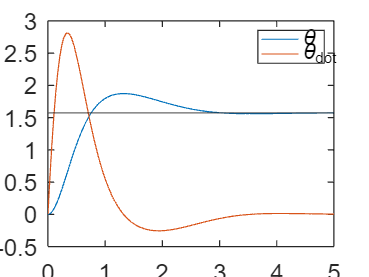


[t, x] = ode45(@(t, x)pendulum(x, theta_d, a, b, c, K), tspan, x0);

plot(t, x)
yline(pi/2)
legend('\theta', '\theta_dot')

%plotting theta, and theta_dot
% the actual x1 of the graph is x1 = theta - theta_dot
% this would have convergence to x1 = 0 and x2 = 0
% it would be good to start the x0 away from pi/2
% some of these are
% this plot is just for fun

function dxdt = pendulum(x, theta_d, a, b, c, K)
    theta = x(1);
    theta_dot = x(2);
    k1 = K(1);
    k2 = K(2);
    T = a/c*sin(theta_d) - k1*(theta - theta_d) - k2*theta_dot;
    %T_d = a/c*sin(theta_d);
    %u = T - T_d;
    dxdt = [x(2); -a*sin(theta) - b*theta_dot + c*T];
end